%% REFERENCE
% Consensus Equilibrium for Super-Resolution and Extreme-Scale CT SC %19, November 17–22, 2019, Denver, CO, USA


%% AC-MBIR Equation
% Algorithm 3 AC-MBIR
% INPUT: The partitioned CT measurements and system matrix.
% LOCAL: G: the number of subsets. vi : the ith LR reconstruction.
%        [vi ]j : the jth sub-volume of vi . [vi ]j,k : the kth SV of [vi ]j .
%        Similar notations apply to wi , ui .
% OUTPUT: x: the consensus HR solution.
% 1: Initialize x, vi , wi , and ui
% 2: while x , vi , i = 1, 2, ...,G do
% 3:    for each subset i do in parallel across clusters
% 4:        for each sub-volume [vi ]j ∈ vi , do in parallel across nodes
% 5:            for each SV [vi ]j,k ∈ [vi ]j , do in parallel across cores
% 6:                [vi ]j,k ← argmin[vi ]j,k Fi ([x]j,k + [ui ]j,k )
% 7:                [(w′)i ]j,k ← [wi ]j,k
% 8:                [wi ]j,k ← (2[vi ]j,k − [x]j,k − [ui ]j,k )
% 9:                [wi ]j,k ← ρ[wi ]j,k +􀀀1 − ρ�[(w′)i ]j,k
% 10:               [x]j,k ← Average([w1]j,k , · · · , [wG]j,k ), through MPI all reduce among nodes in a cabinet
% 11:               [ui ]j,k ← [x]j,k − [wi ]j,k
% 12:           end for
% 13:       end for
% 14:       Neighboring sub-volumes exchange boundary voxels through MPI send/receive operations.
% 15:   end for
% 16: end while
%% 


clear ;

isgpu   = true;


addpath(genpath('./utilities/'));
addpath(genpath('./denoisers/'));
% addpath(genpath('D:\software\MATLAB\R2021a\toolbox\astra-1.9.0.dev11-matlab-win-x64'));
% addpath(genpath('D:\software\MATLAB\R2021a\toolbox\TIGRE_toolbox\TIGRE-master'));

#### SYSTEM SETTING


N       = 128;
% ANG     = 180;
ANG     = pi;       % Angle range 0-180

G       = 3;        % Number of subsets
J       = 2;        % Number of sub-volumes
K       = 2;        % Number of super voxels

VIEW_F    = 360;    % Full view   
VIEW    = 360/G;
THETA   = zeros(G,VIEW);
Offset  = zeros(1,G);

THETA_F   = linspace(0, ANG, VIEW_F + 1);   THETA_F(end) = [];              % Full view angles

% A       = cell(1,G);
% AT      = cell(1,G);
% AINV    = cell(1,G);


#### DATA GENERATION


%% Define Geometry
% 
% VARIABLE                                   DESCRIPTION                    UNITS
%-------------------------------------------------------------------------------------
geo.DSD = 2000;                             % Distance Source Detector      (mm)
geo.DSO = 1000;                             % Distance Source Origin        (mm)
% Detector parameters

% Make the pixels in the detector the same size as the image voxels
% (or viceversa)!

geo.nDetector=[N; N];					% number of pixels              (px)
geo.dDetector=[5.5; 5.5]; 					% size of each pixel            (mm)
geo.sDetector=geo.nDetector.*geo.dDetector; % total size of the detector    (mm)
% Image parameters
geo.nVoxel=[N;N;N];                   % number of voxels              (vx)
geo.dVoxel=[4;4;4];          % size of each voxel            (mm)
geo.sVoxel=geo.nVoxel.*geo.dVoxel;        % total size of the image       (mm)
% Offsets
geo.offOrigin =[0;0;0];                     % Offset of image from origin   (mm)              
geo.offDetector=[0;0];                     % Offset of Detector            (mm)
% Auxiliary 
geo.accuracy=0.5;                           % Accuracy of FWD proj          (vx/sample)


%% As easy as this:
geo.mode='parallel';
% geo.mode='cone';
head=headPhantom(geo.nVoxel);

A_F       = @(x) Ax(x, geo, THETA_F);       % System matrix A operator
% AT_F      = @(y) iradon(y, THETA_F, 'none', N)/(pi/(2*length(THETA)));
AINV_F    = @(y) FDK(y, geo, THETA_F);

% denoiser= @wrapper_TV;
denoiser= @im3DDenoise;

for i = 1 : G
    
    Offset(i)   = (i-1)* (ANG/G/VIEW);              % View subsets
    THETA(i,:)  = linspace(0 + Offset(i), ANG - ANG/VIEW + Offset(i), VIEW);  % THETA(i,end) = [];

end

% N_J = N/J;
% N_K = N/K;

geo_s = cell(J,K);                  % Geometry setting for each super-voxel

for j = 1 : J
    for k = 1 : K
        
        geo_s{j,k} = geo;
        % Image parameters
        geo_s{j,k}.nDetector(1)=geo.nDetector(1)/J;         % number of pixels              (px)
%        geo_s{j,k}.nDetector(2)=geo.nDetector(2)/K;         % size of each pixel            (mm)
        geo_s{j,k}.sDetector = geo_s{j,k}.nDetector.*geo_s{j,k}.dDetector; % total size of the detector    (mm)
        
        geo.offDetector=[0;0];                     % Offset of Detector            (mm)
        
        geo_s{j,k}.nVoxel(1)=geo.nVoxel(1)/J; 
        geo_s{j,k}.nVoxel(2)=geo.nVoxel(2)/K;           % number of voxels              (vx)
%         geo_s{j,k}.sVoxel(1)=geo.sVoxel(1)/J;
%         geo_s{j,k}.sVoxel(2)=geo.sVoxel(2)/K;           % total size of the image       (mm)
        geo_s{j,k}.sVoxel=geo_s{j,k}.nVoxel.*geo_s{j,k}.dVoxel;       % size of each voxel            (mm)
% Offsets
%         geo_s{j,k}.offOrigin =[-geo_s{j,k}.sVoxel(1)*(j-1/2)+geo.sVoxel(1)/2;-geo_s{j,k}.sVoxel(2)*(k-1/2)+geo.sVoxel(2)/2;0];                     % Offset of image from origin   (mm)              
%         geo_s{j,k}.offDetector =[-geo_s{j,k}.sDetector(1)*(j-1/2)+geo.sDetector(1)/2;-geo_s{j,k}.sDetector(2)*(k-1/2)+geo.sDetector(2)/2]; 
    end
end

    A        = @(x,geo_,THETA_) Ax(x, geo_, THETA_);    % Partition of system matrix A operator    
    AT       = @(y,geo_,THETA_) FDK(y, geo_, THETA_)/(pi/(2*length(THETA_)));
    AINV     = @(y,geo_,THETA_) FDK(y, geo_, THETA_);


% load('XCAT512.mat');

% x       = imresize3(double(head), size(head));
x = head;

p       = cell(1,G);
pn      = cell(1,G);
y       = cell(1,G);
v       = cell(1,G);
% v       = cell(1,G);

p_F     = A_F(x);
x_full  = AINV_F(p_F);


pn_F       = addCTnoise(p_F);
i0          = 6e5;                  % Set Poisson noise scaling factor
y_F         = pn_F;
v_F         = AINV_F(y_F);


v_s      = cell(G,J,K);
y_s      = cell(G,J,K);

for i = 1 : G

    p{i}        = A(x,geo,THETA(i,:));
    % x_full    = AINV(p);
    
    %% LOW-DOSE SINOGRAM GENERATION
    
%     pn{i}       = exp(-p{i});
%     pn{i}       = i0.*pn{i};
%     pn{i}       = poissrnd(pn{i});
%     pn{i}       = max(-log(max(pn{i},1)./i0),0);
    
    pn{i}       = addCTnoise(p{i});     % Add Poisson and Gaussian noise
    y{i}        = pn{i};
    
    %% Statistical Reconstruction Technique (ART) INITIALIZATION
    v{i}        = AINV(y{i},geo,THETA(i,:));
    
    
% initial state allocation and projection partition for each super-voxel    
for j = 1 : J
        for k = 1 : K
            v_s{i,j,k} = v{i}((geo.nVoxel(1)/J*(j-1)+1:geo.nVoxel(1)/J*j),(geo.nVoxel(2)/K*(k-1)+1:geo.nVoxel(2)/K*k),:);
            y_s{i,j,k} = A(v_s{i,j,k}, geo_s{j,k},THETA(i,:)) ; 
        end
    end

end


x0          = v{1};         % Set initial state of reconstruction
alpha      = 0.5;           % Set Gradent descent step size
niter       = 2e1;          % Set iteration number
bpos        = true;         % Non-nagetiveness
lambda       = 1/sqrt(i0);  % Set denoiser parameter
sigma2      = 5*G;          % Set proximal function scaling factor
rho         = 0.9;          % Set Mann update parameter
tol         = 1e-8;         % Set tolerance

#### RUN Statistical Reconstruction Technique (ART)

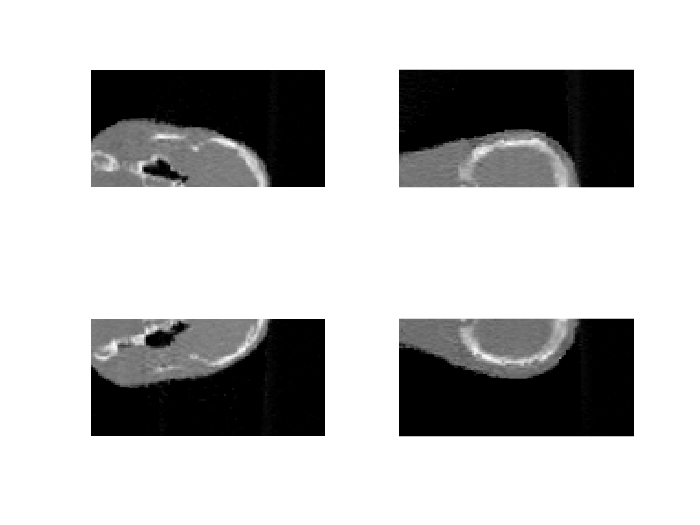

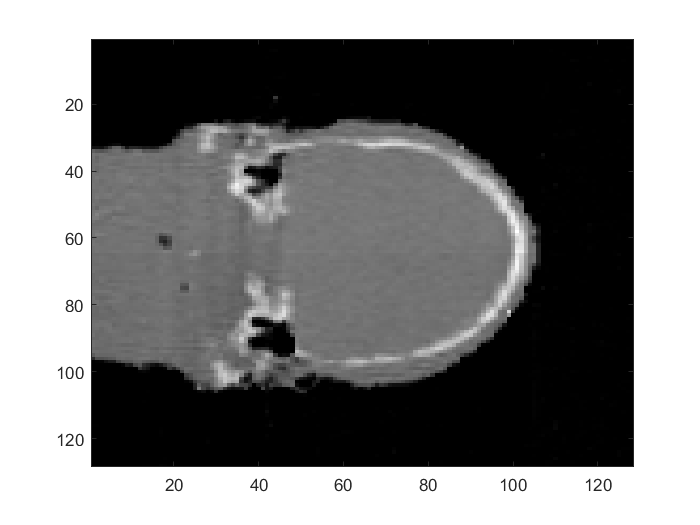


% if isgpu
%     y{i} = gpuArray(y{i});
%     x0 = gpuArray(x0);
% end

 tic
 
x_art   = AC_MBIR_3d(A,AT,y_s,x0,geo_s,THETA,G,J,K,denoiser,lambda,alpha,sigma2,rho,niter,bpos);        % Implement the reconstruction algorithm 3d

t3 = toc

t3 = 109.3067

#### CALCULATE QUANTIFICATION FACTOR

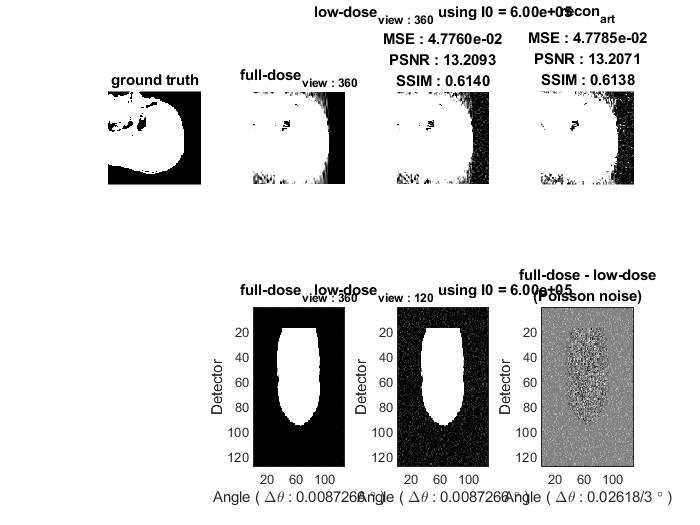



x_low       = max(v_F, 0);
x_art       = max(x_art, 0);
nor         = max(x(:));

mse_x_low   = immse(x_low./nor, x./nor);
mse_x_art   = immse(x_art./nor, x./nor);

psnr_x_low  = psnr(x_low./nor, x./nor);
psnr_x_art  = psnr(x_art./nor, x./nor);

ssim_x_low  = ssim(x_low./nor, x./nor);
ssim_x_art  = ssim(x_art./nor, x./nor);


%% DISPLAY
wndImg  = [0, 0.03];
wndPrj  = [0, 6];

figure;
colormap(gray(256));

x_slide(:,:) = x(round(end/2),:,:);
x_full_slide(:,:) = x_full(round(end/2),:,:);
v_F_slide(:,:) = v_F(round(end/2),:,:);
x_art_slide(:,:) = x_art(round(end/2),:,:);

% x_slide(:,:) = x(:,round(end/2),:);
% x_full_slide(:,:) = x_full(:,round(end/2),:);
% v_F_slide(:,:) = v_F(:,round(end/2),:);
% x_art_slide(:,:) = x_art(:,round(end/2),:);
% suptitle('Algebraic Reconstruction Technique');


subplot(241);   imagesc(x_slide,      wndImg);    axis image off;     title(['ground truth']);

subplot(242);   imagesc(x_full_slide, wndImg);    axis image off;     title(['full-dose_{view : ', num2str(VIEW_F) '}']);
subplot(246);   imagesc(p_F(:,:,round(end/2)), wndPrj);         xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['full-dose_{view : ', num2str(VIEW_F) '}']);

subplot(243);   imagesc(v_F_slide,  wndImg);    axis image off;     title({['low-dose_{view : ', num2str(VIEW_F) '}' ' using I0 = ' num2str(i0, '%.2e') ], ['MSE : ' num2str(mse_x_low, '%.4e')], ['PSNR : ' num2str(psnr_x_low, '%.4f')], ['SSIM : ' num2str(ssim_x_low, '%.4f')]});
subplot(247);   imagesc(y_F(:,:,round(end/2)),  wndPrj);        xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['low-dose_{view : ', num2str(VIEW) '} using I0 = ' num2str(i0, '%.2e')]);

subplot(244);   imagesc(x_art_slide,  wndImg);    axis image off;     title({['recon_{art}'], ['MSE : ' num2str(mse_x_art, '%.4e')], ['PSNR : ' num2str(psnr_x_art, '%.4f')], ['SSIM : ' num2str(ssim_x_art, '%.4f')]});
subplot(248);   imagesc(y_F(:,:,round(end/2)) - p_F(:,:,round(end/2)));             xlabel( [ 'Angle ( \Delta\theta : ' num2str(ANG/VIEW) '/' num2str(G)  ' \circ )' ] );   ylabel('Detector'); title({['full-dose - low-dose'],'(Poisson noise)'});